### Question 1: Part a

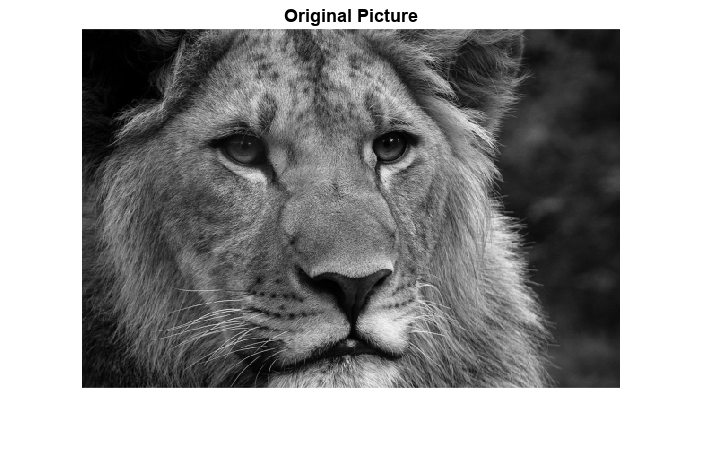

Origin_Image = imread('Lion.png');  
imshow(Origin_Image)
title("Original Picture")

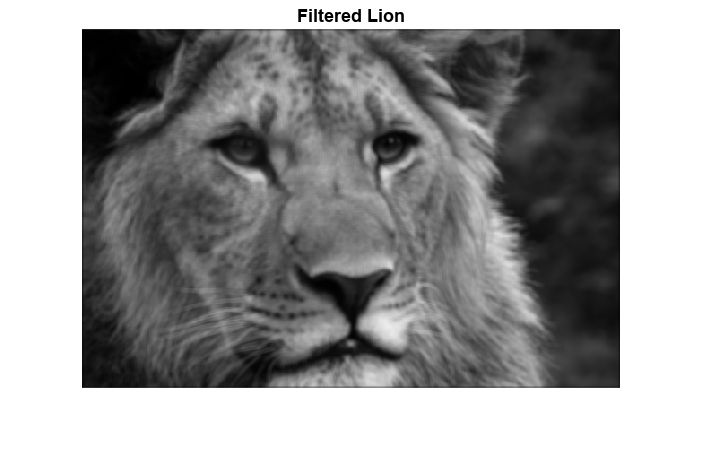

Filter = ones(5,5)/25;
% Setting the filter to be a 5/5 array of ones, then dividing by 25 making
% the weight of each pixel to be 1

Filtered_Image = imfilter(Origin_Image, Filter);
imshow(Filtered_Image)
title("Filtered Lion")

% This is the lion with a filter on it 

%This image is blurier than the initial image due to the averaging of pixels using the 5x5 filter. 

### Question 1: Part b

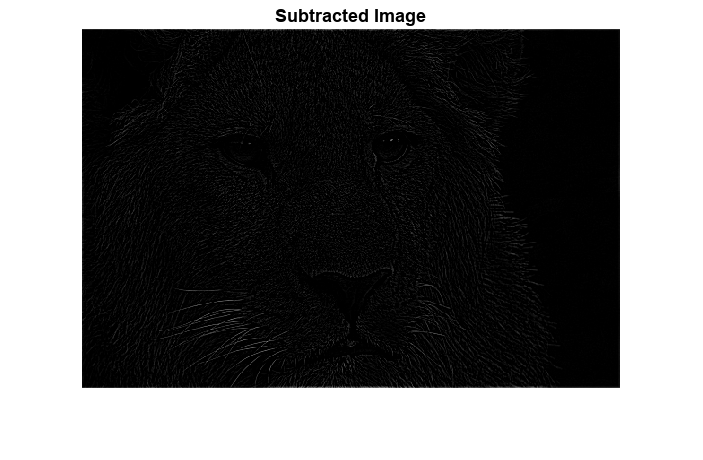

New_Image = Origin_Image - Filtered_Image;
imshow(New_Image)
title("Subtracted Image")

% The resulting image is a darkened version of the details that were
% blurred out of the image after it was filtered. These resemble the edges
% from the original picture which can help with detail or line detection.

### Question 1: part c

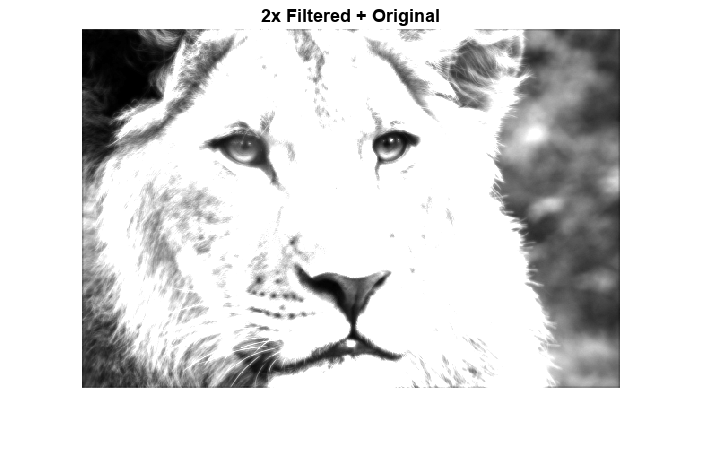

TwoxSubtract = (2 * Filtered_Image);
New_Image = (Origin_Image + TwoxSubtract);
imshow(New_Image)
title("2x Filtered + Original")

%The resulting image has both blurrier and sharper aspects to it. While the
%majority of the picture is blurry and overexposed, the edges and small
%details like the hairs on the lions face were more exposed. Only the
%darker details like the eys, nose, and mouth were still recognizable. 

### Question 1: part d

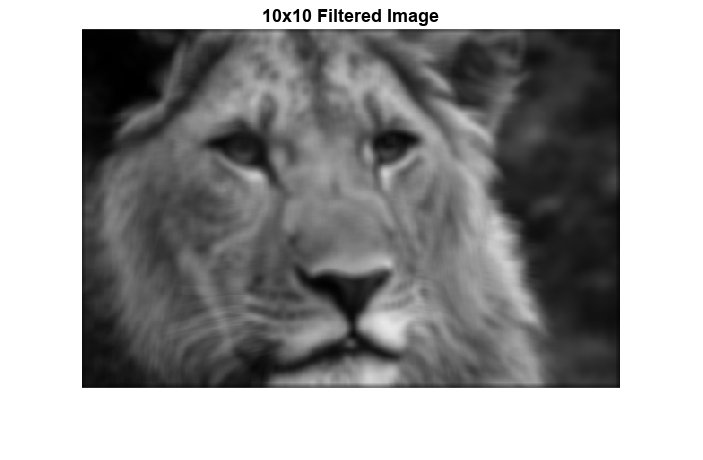

%Repeat parts a through c using 10x10 filter of unit weight. 
Filter10x10 = (ones(10,10)/100);

BiggerFilteredImage = imfilter(Origin_Image, Filter10x10);
imshow(BiggerFilteredImage)
title("10x10 Filtered Image")

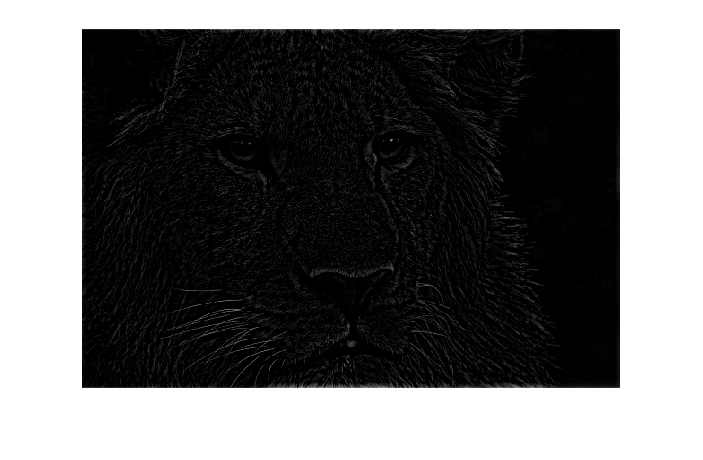

New_Image2 = Origin_Image - BiggerFilteredImage;
imshow(New_Image2)

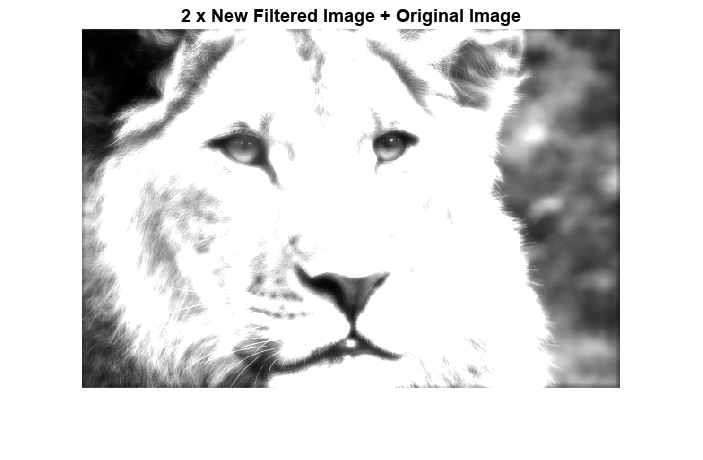

title("New subtracted image")
 
%More edges are visible than in the initial subtracted image. They are
%clearer than the orignals as well. 

TwoFiltered_Image = (2 * BiggerFilteredImage);
Newer_Image = (Origin_Image + TwoFiltered_Image);
imshow(Newer_Image)
title("2 x New Filtered Image + Original Image")


% The image is blurrier than the first version of the (2xFilteredImage +
% Original Image). The border between the light and dark sections of the
% image are more established. 